# Abgabe Numerik Programmierblatt 1

## Matthias Gültig - Matrikelnummer: 3469020 

Aufgabe 1 - Euler (siehe function)

Aufgabe 1 - Heun (siehe function)

Aufgabe 1 - Runge-Kutta (siehe function)

Aufgabe 2a)

Räuber Beute DGL

Aufgabe 2a) Visualisierungen

%{
initialisiere Parameter
Intervall I = [0,T]
Anfangswert y0 in IR^d 
Zeitschritte tau in IR^+
%}

y_0 = [0.5; 0.5];
T = 20;

%Initialisiere Zeitschritte
tau1 = 0.64;
tau2 = 0.32;
tau3 = 0.16;
tau4 = 0.08;
tau5 = 0.04;


%{
rufe Funktionen für verschiedene taus auf. Im Beispiel tau1 und tau 5
solExplEuler: Lösungsmatrix vom Euler
solExplHeun: Lösungsmatrix vom Heun
%}
solExplEulerTau1 = explicit_euler(@rabeu, y_0, T, tau1)

solExplEulerTau1 = 	1.0e+158 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    6.0330       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -6.0330      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf      -Inf


solExplHeunTau1 = explicit_heun(@rabeu, y_0, T, tau1)

solExplHeunTau1 =     0.5000    0.7194    1.0816    1.6173    2.2102    2.1516    0.9393    0.4716    0.3534    0.3692    0.4704    0.6692    1.0032    1.5105    2.1245    2.2832    1.1097    0.5551    0.3933    0.3909    0.4804    0.6654    0.9776    1.4478    2.0119    2.1868    1.1878    0.5889    0.4103    0.4008    0.4859    0.6662
    0.5000    0.3830    0.3490    0.4206    0.7322    1.6765    2.4994    1.7113    1.1526    0.7668    0.5278    0.3951    0.3461    0.3934    0.6409    1.4404    2.5688    1.7753    1.2299    0.8311    0.5771    0.4331    0.3766    0.4176    0.6472    1.3570    2.3973    1.7899    1.2553    0.8542    0.5957    0.4481


solExplRungeKutta1 = explicit_runge_kutta3(@rabeu, y_0, T, tau1)

solExplRungeKutta1 = 	1.0e+288 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    1.3774       Inf       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -1.3774      -Inf       NaN       NaN       NaN       NaN       NaN       NaN       NaN


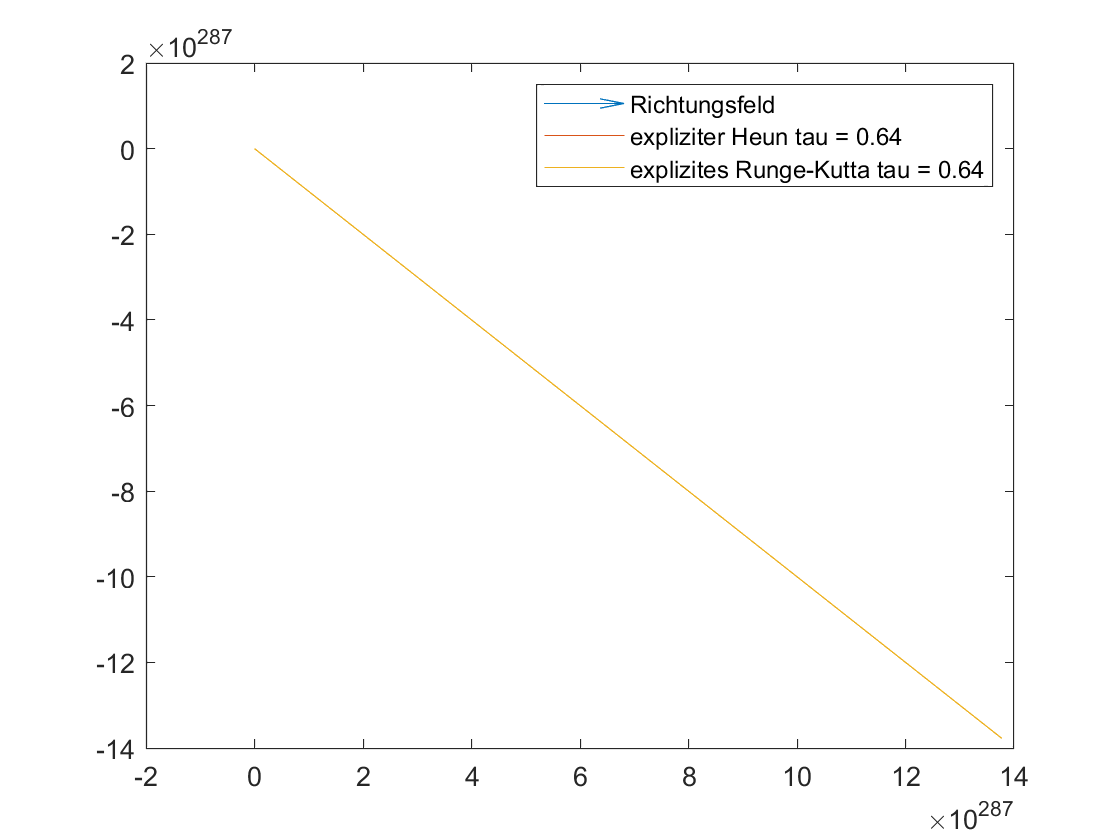


% visualisiere Lösungskurven -> tau zu groß!!
[x,y] = meshgrid(0:0.1:3,0:0.1:3);
dx = (1-y).*x;
dy = (x-1).*y;
quiver(x,y,dx,dy, 'DisplayName', 'Richtungsfeld');
hold on;
plot(solExplHeunTau1(1,:), solExplHeunTau1(2,:), 'DisplayName', 'expliziter Heun tau = 0.64');
hold on;
plot(solExplRungeKutta1(1,:), solExplRungeKutta1(2,:), 'DisplayName', 'explizites Runge-Kutta tau = 0.64');
legend;
hold off;

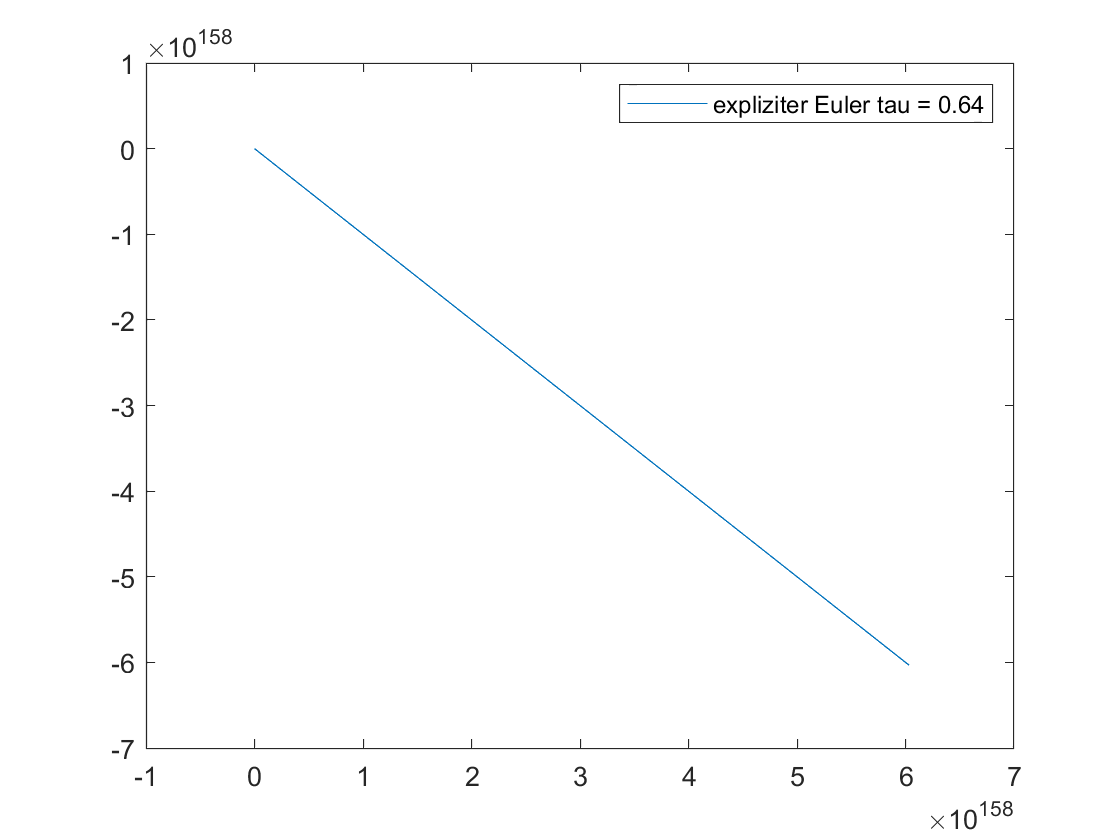


plot(solExplEulerTau1(1,:), solExplEulerTau1(2,:), 'DisplayName', 'expliziter Euler tau = 0.64');
legend;
hold off;


% visualisiere Lösungskurven
solExplEulerTau5 = explicit_euler(@rabeu, y_0, T, tau5)

solExplEulerTau5 =     0.5000    0.5100    0.5204    0.5312    0.5425    0.5541    0.5662    0.5788    0.5918    0.6053    0.6192    0.6337    0.6486    0.6640    0.6800    0.6965    0.7135    0.7311    0.7493    0.7680    0.7873    0.8072    0.8277    0.8488    0.8706    0.8930    0.9160    0.9396    0.9640    0.9889    1.0146    1.0409    1.0679    1.0956    1.1239    1.1530    1.1826    1.2130    1.2440    1.2756    1.3079    1.3408    1.3742    1.4082    1.4427    1.4777    1.5132    1.5490    1.5852    1.6216
    0.5000    0.4900    0.4804    0.4712    0.4623    0.4539    0.4458    0.4381    0.4307    0.4236    0.4170    0.4106    0.4046    0.3989    0.3935    0.3885    0.3838    0.3794    0.3753    0.3715    0.3681    0.3650    0.3621    0.3597    0.3575    0.3556    0.3541    0.3529    0.3521    0.3516    0.3514    0.3516    0.3522    0.3531    0.3545    0.3562    0.3584    0.3610    0.3641    0.3677    0.3717    0.3763    0.3814    0.3871    0.3935    0.4004    0.4081    0.4165

solExplHeunTau5 = explicit_heun(@rabeu, y_0, T, tau5)

solExplHeunTau5 =     0.5000    0.5102    0.5208    0.5318    0.5433    0.5552    0.5675    0.5803    0.5935    0.6073    0.6215    0.6362    0.6514    0.6671    0.6833    0.7001    0.7174    0.7353    0.7537    0.7728    0.7924    0.8126    0.8334    0.8548    0.8769    0.8996    0.9229    0.9469    0.9716    0.9968    1.0228    1.0494    1.0767    1.1046    1.1332    1.1625    1.1924    1.2229    1.2540    1.2858    1.3181    1.3509    1.3843    1.4182    1.4525    1.4872    1.5222    1.5575    1.5930    1.6287
    0.5000    0.4902    0.4808    0.4718    0.4631    0.4548    0.4469    0.4394    0.4322    0.4253    0.4188    0.4126    0.4068    0.4013    0.3961    0.3912    0.3867    0.3825    0.3786    0.3750    0.3718    0.3689    0.3663    0.3640    0.3620    0.3604    0.3591    0.3582    0.3576    0.3574    0.3575    0.3580    0.3589    0.3602    0.3619    0.3641    0.3667    0.3697    0.3733    0.3773    0.3819    0.3871    0.3928    0.3991    0.4061    0.4138    0.4223    0.4315 

solExplRungeKutta5 = explicit_runge_kutta3(@rabeu, y_0, T, tau5)

solExplRungeKutta5 =     0.5000    0.5000    0.5100    0.5202    0.5308    0.5418    0.5533    0.5652    0.5775    0.5903    0.6035    0.6172    0.6314    0.6461    0.6613    0.6770    0.6932    0.7100    0.7273    0.7451    0.7635    0.7825    0.8021    0.8223    0.8431    0.8645    0.8866    0.9093    0.9326    0.9566    0.9813    1.0066    1.0326    1.0593    1.0867    1.1147    1.1435    1.1729    1.2031    1.2339    1.2653    1.2975    1.3303    1.3637    1.3977    1.4323    1.4675    1.5031    1.5393    1.5759
    0.5000    0.5000    0.4900    0.4802    0.4708    0.4618    0.4531    0.4448    0.4369    0.4294    0.4222    0.4153    0.4088    0.4026    0.3967    0.3912    0.3860    0.3811    0.3765    0.3722    0.3683    0.3646    0.3613    0.3583    0.3556    0.3532    0.3511    0.3494    0.3479    0.3468    0.3461    0.3456    0.3455    0.3458    0.3464    0.3475    0.3489    0.3507    0.3529    0.3555    0.3586    0.3622    0.3662    0.3708    0.3759    0.3816    0.3879    0.39

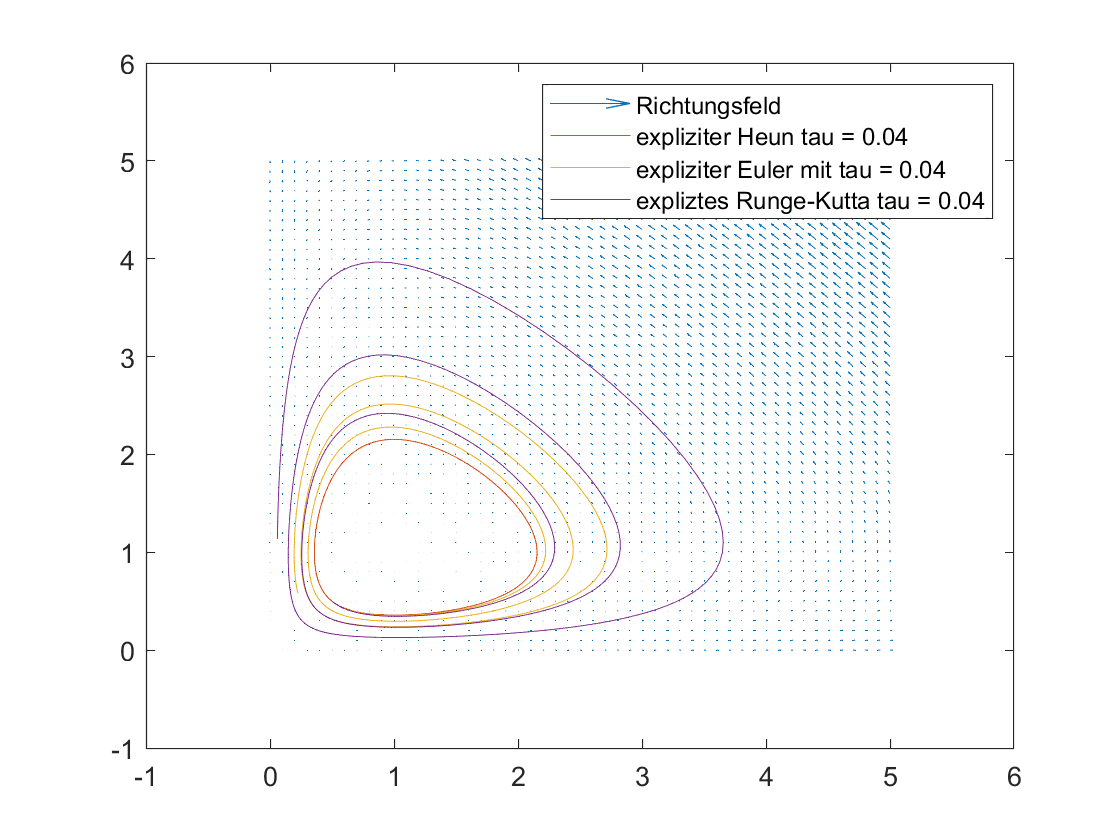

[x,y] = meshgrid(0:0.1:5,0:0.1:5);
dx = (1-y).*x;
dy = (x-1).*y;

quiver(x,y,dx,dy, 'DisplayName', 'Richtungsfeld');
hold on;
plot(solExplHeunTau5(1,:), solExplHeunTau5(2,:), 'DisplayName', 'expliziter Heun tau = 0.04');
hold on;
plot(solExplEulerTau5(1,:), solExplEulerTau5(2,:), 'DisplayName', 'expliziter Euler mit tau = 0.04');
hold on;
plot(solExplRungeKutta5(1,:), solExplRungeKutta5(2,:), 'DisplayName', 'expliztes Runge-Kutta tau = 0.04');
legend;
hold off;

Aufgabe 2b) 

x = (0:tau:T)

x =          0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    1.0400    1.0800    1.1200    1.1600    1.2000    1.2400    1.2800    1.3200    1.3600    1.4000    1.4400    1.4800    1.5200    1.5600    1.6000    1.6400    1.6800    1.7200    1.7600    1.8000    1.8400    1.8800    1.9200    1.9600


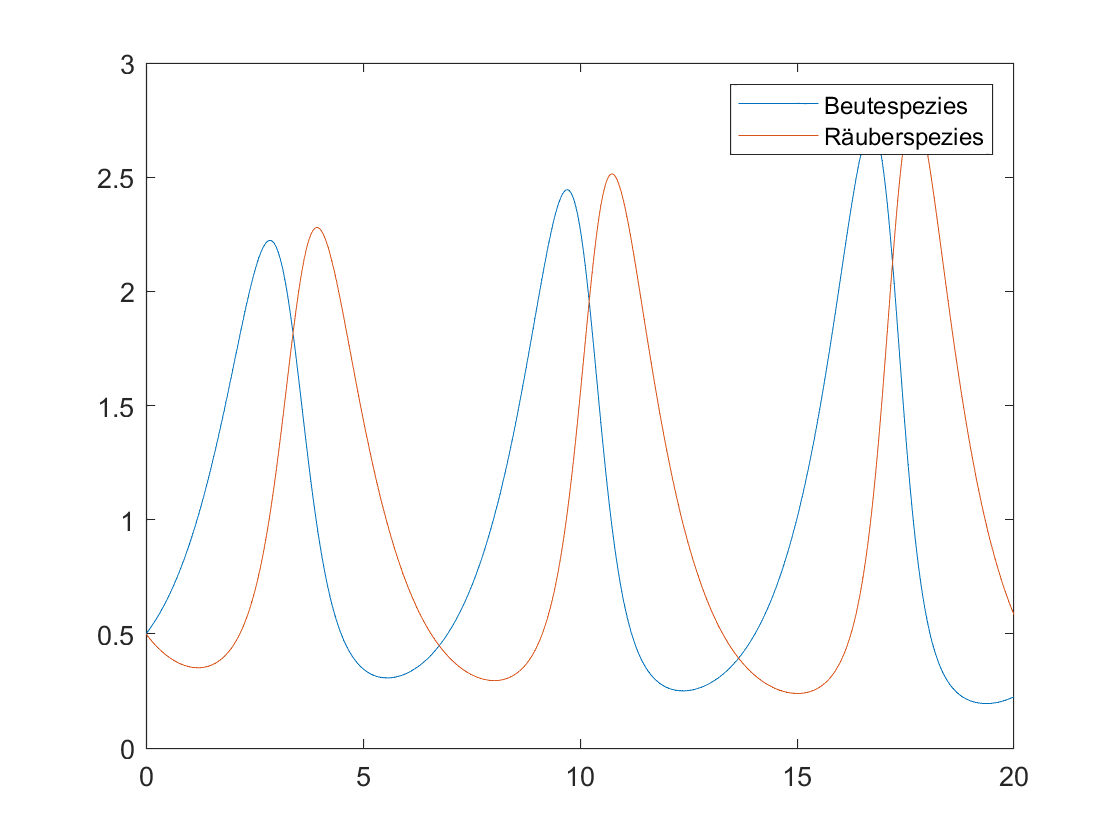

plot(x,solExplEuler(1,:),'DisplayName', 'Beutespezies');
hold on
plot(x,solExplEuler(2,:),'DisplayName', 'Räuberspezies');
legend;
hold off;

Aufgabe 2c)

Euler hat Probleme bei zu großer Zeitschrittweite -> schlecht konditioniert?

Stataionäre DGL kommt bei Euler zum Tragen

Aufgabe 3

a)